# v_icam_oiedges

Zhenyi and BW went through a comparison of the new wvf shift invariant calculations (built for the flare case) in the dev-flare branch, and the computations in the dev branch.

After fixing the Marimont-Wandell issue, the dev and dev-flare branches now differ (fail to pass) validations for tests. These appear to be differences related to the convolutions. 

Here we flipped back and forth between the branches and compared the OI convolutions. We observed that

So rather than returning to the dev calculation, we think we should stick with the dev-flare calculation. It fixes some problems with the HDR calculations and is very close to the dev calculations. 

We also tested with the sensor/ip MTF calculations. The dev-flare matches diffraction limited more closely.

We left the Marimont-Wandell calculation using the old path.

ieInit;

scene = sceneCreate('slanted bar');
scene = sceneSet(scene,'fov',1);

## We use opticsPSF (default) method

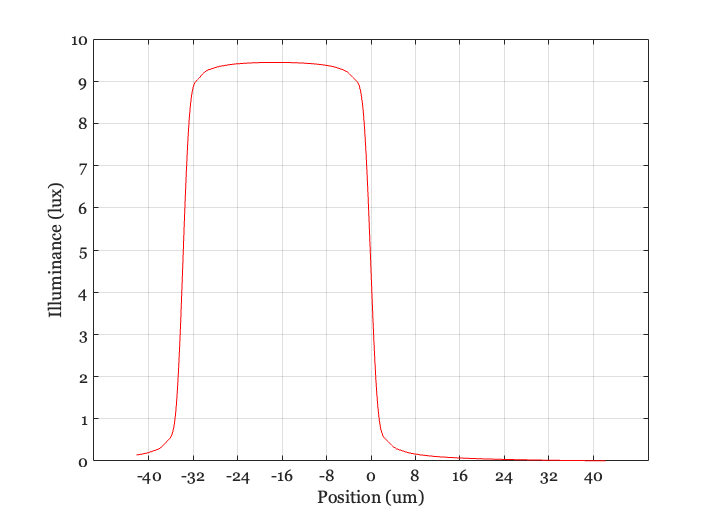

oiPSF = oiCreate('shift invariant');
oiPSF = oiCompute(oiPSF,scene);
% oiWindow(oi);

uDataPSF = oiPlot(oiPSF,'illuminance hline',[1 240]);

## We use the opticsOTF method

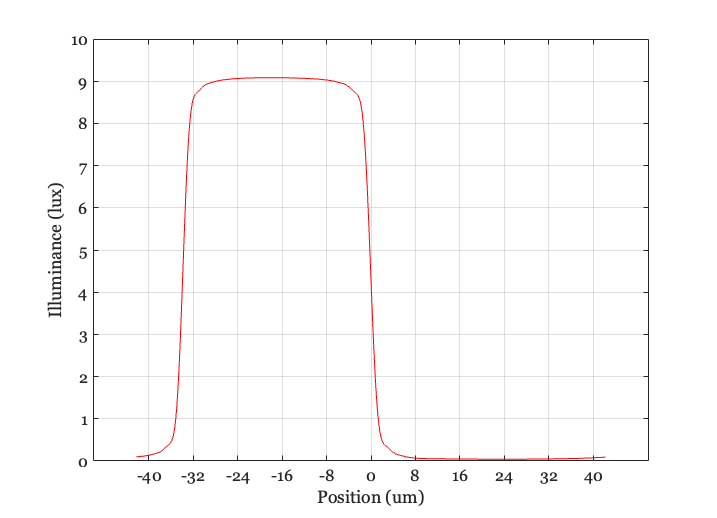

oiOTF = oiCreate('shift invariant');
oiOTF = oiSet(oiOTF,'optics name','opticsotf');

oiOTF = oiCompute(oiOTF,scene);
% oiWindow(oi);

% Run with dev
uDataOTF = oiPlot(oiOTF,'illuminance hline',[1 240]);

## The illuminance computed from the two branches is not the same

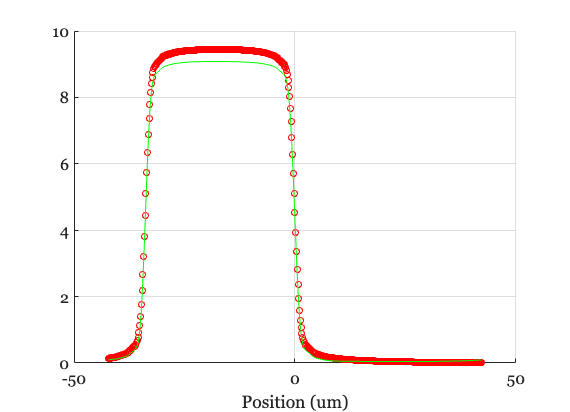

ieNewGraphWin;
hold on;
plot(uDataPSF.pos,uDataPSF.data,'o');
plot(uDataOTF.pos,uDataOTF.data,'-');
grid on;
xlabel('Position (um)');

## We then decided to see which was closer to the diffraction limited case

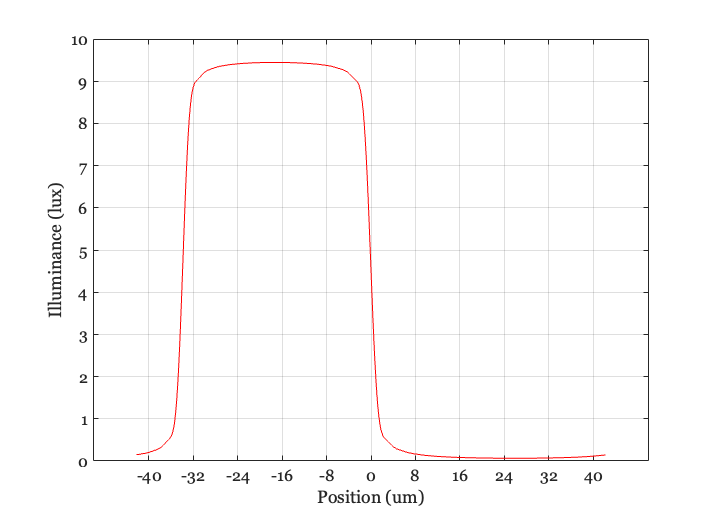

% We first confirmed that this was the same on both branches (not
% shown).
oiDL = oiCreate('diffraction limited');
oiDL = oiCompute(oiDL,scene);
uDataOTFDL = oiPlot(oiDL,'illuminance hline',[1 240]);

## Diffraction limited is identical on the two branches

%{
uDataOTFDL = oiPlot(oiDL,'illuminance hline',[1 240]);
uDataOTFFlareDL = oiPlot(oiDL,'illuminance hline',[1 240]);

% Perfect match

ieNewGraphWin;
plot(uDataOTFFlareDL.pos,uDataOTFFlareDL.data,'o');
hold on;
plot(uDataOTFDL.pos,uDataOTFDL.data,'-');

ieNewGraphWin;
plot(uDataOTFFlareDL.data(:),uDataOTFDL.data(:),'.');
identityLine;
%}

## Here is a comparison of diffraction limited with dev-flare and dev

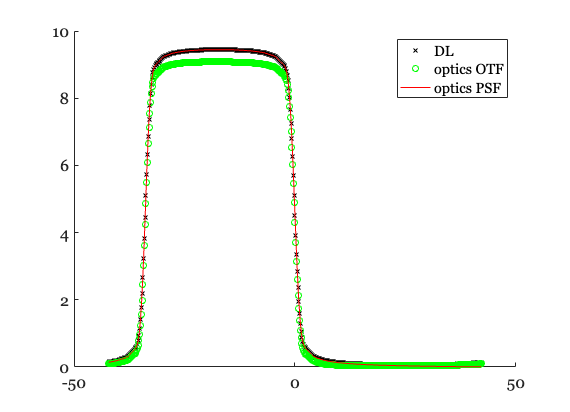

ieNewGraphWin;
hold on;
plot(uDataOTFDL.pos,uDataOTFDL.data,'kx');
plot(uDataOTF.pos,uDataOTF.data,'go');
plot(uDataPSF.pos,uDataPSF.data,'r-');
legend({'DL','optics OTF','optics PSF'});

## Here are slices through the PSF

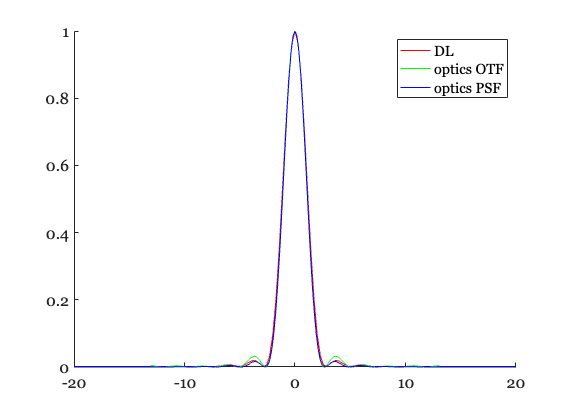

psfDL = oiGet(oiDL,'optics psf data',550); psfDL.psf = ieScale(psfDL.psf,1);
psfDev = oiGet(oiOTF,'optics psf data',550);psfDev.psf = ieScale(psfDev.psf,1);
psfDevFlare = oiGet(oiPSF,'optics psf data',550); psfDevFlare.psf = ieScale(psfDevFlare.psf,1);

ieNewGraphWin;
hold on;
plot(psfDL.xy(1,:,1), psfDL.psf(26,:));
plot(psfDev.xy(1,:,1), psfDev.psf(101,:));
plot(psfDevFlare.xy(1,:,1), psfDevFlare.psf(241,:));
legend({'DL','optics OTF','optics PSF'});
set(gca,'xlim',[-20 20]);

## Show the LSF comparisons

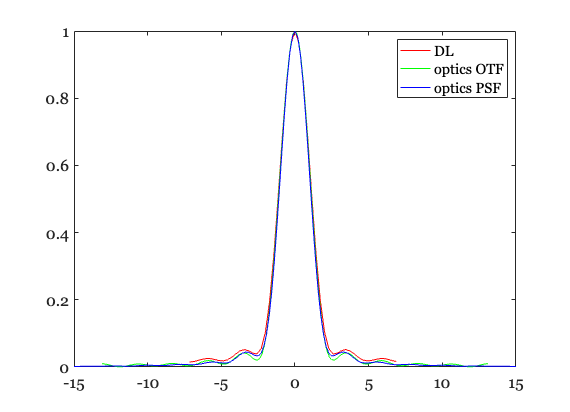

lsfDL       = psf2lsf(psfDL.psf); lsfDL = ieScale(lsfDL,1);
lsfDev      = psf2lsf(psfDev.psf);lsfDev = ieScale(lsfDev,1);
lsfDevFlare = psf2lsf(psfDevFlare.psf); lsfDevFlare = ieScale(lsfDevFlare,1);

ieNewGraphWin;
plot(psfDL.xy(1,:,1),lsfDL); hold on;
plot(psfDev.xy(1,:,1),lsfDev);
plot(psfDevFlare.xy(1,:,1),lsfDevFlare);
legend({'DL','optics OTF','optics PSF'});
set(gca,'xlim',[-15 15]);

%{

uDataPSFDL = oiPlot(oiDL,'psf 550');
uDataPSFDevFlare = oiPlot(oiPSF,'psf 550');
uDataPSFDev = oiPlot(oiOTF,'psf 550');

ieNewGraphWin;
hold on;
plot(uDataPSFDL.x(25,:), uDataPSFDL.psf(25,:));
plot(uDataPSFDev.x(100,:), uDataPSFDev.psf(100,:));
plot(uDataPSFDevFlare.x(240,:), uDataPSFDevFlare.psf(240,:));
legend({'DL','Dev','Dev-Flare'});
set(gca,'xlim',[-20 20]);
%}

sensor = sensorCreate('imx363');
sensor = sensorSet(sensor,'fov',1,oiOTF);
sensor = sensorSet(sensor,'noise flag',0);
ip = ipCreate;

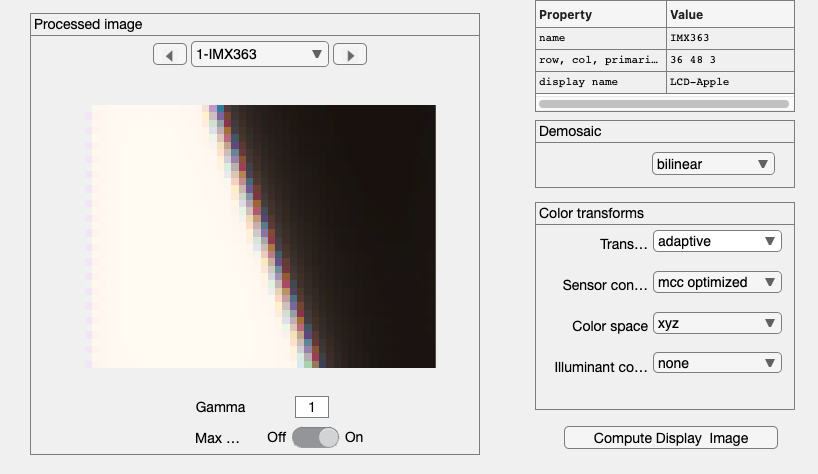

sensor = sensorCompute(sensor,oiDL);
ip = ipCompute(ip,sensor);
ipWindow(ip);

ieISO12233(ip,sensor);

No black border detected


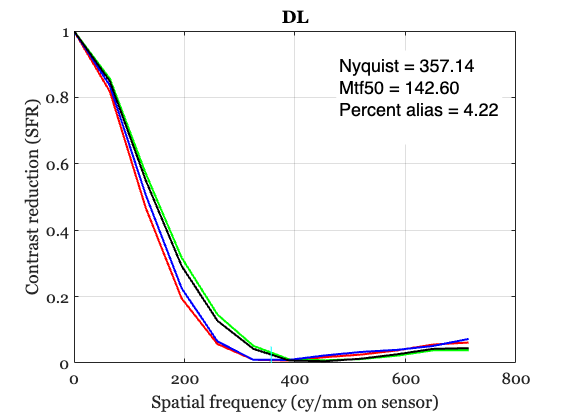

title('DL');


sensor = sensorCompute(sensor,oiOTF);
ip = ipCompute(ip,sensor);
ieISO12233(ip,sensor);

No black border detected


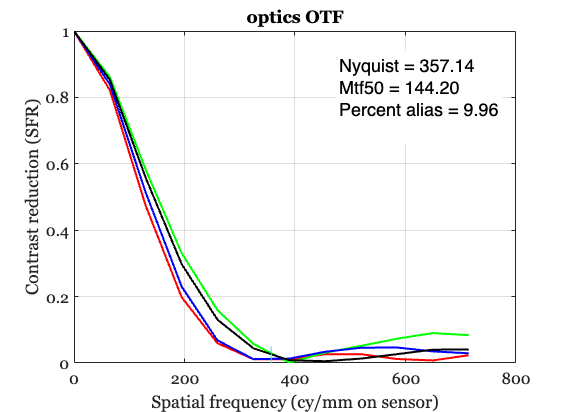

title('optics OTF');


sensor = sensorCompute(sensor,oiPSF);
ip = ipCompute(ip,sensor);
ieISO12233(ip,sensor);

No black border detected


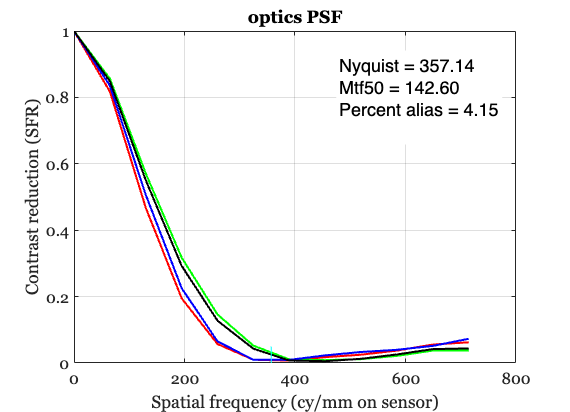

title('optics PSF');